# Compare HDR versus Burst

experiment with various HDR and other multi-image "burst" algorithms for capturing scenes with a variety of dynamic ranges, as well as object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200

sceneLuminance = 200

numRays = 256

numRays = 256

filmResolution = 256

filmResolution = 256

pbrtLensFile = false

pbrtLensFile = logical
   0


sceneChoice = "CornellBoxReference"

sceneChoice = "CornellBoxReference"

apertureDiameter = 6% in mm

apertureDiameter = 6

if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);
end

Read 9 materials
Reading C4D geometry information.


## Create our sample camera

Just one module

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

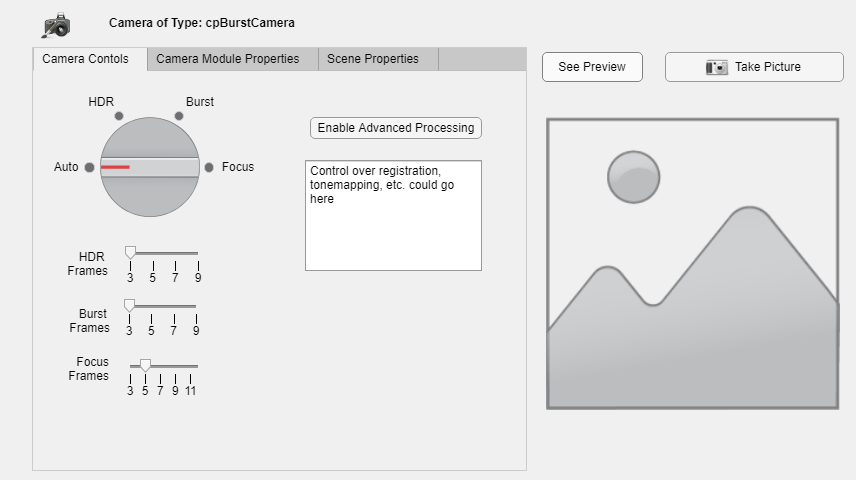

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp657998fe_7355_4315_8739_4efc355f3ab9
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp657998fe_7355_4315_8739_4efc355f3ab9 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp657998fe_7355_4315_8739_4efc355f3ab9\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp657998fe_7355_4315_8739_4efc355f3ab9\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp657998fe_7355_4315_8739_4efc355f3ab9 -v C:/iset/iset3d/local/CornellBoxReference/tp657998fe_7355_4315_8739_4efc355f3ab9:/tp657998fe_7355_4315_8739_4efc355f3ab9 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae -v C:/iset/iset3d/local/CornellBoxReference/tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae:/tpb0ed7fcf_5e1c_4fa6_8b2a_66d6b274e4ae vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

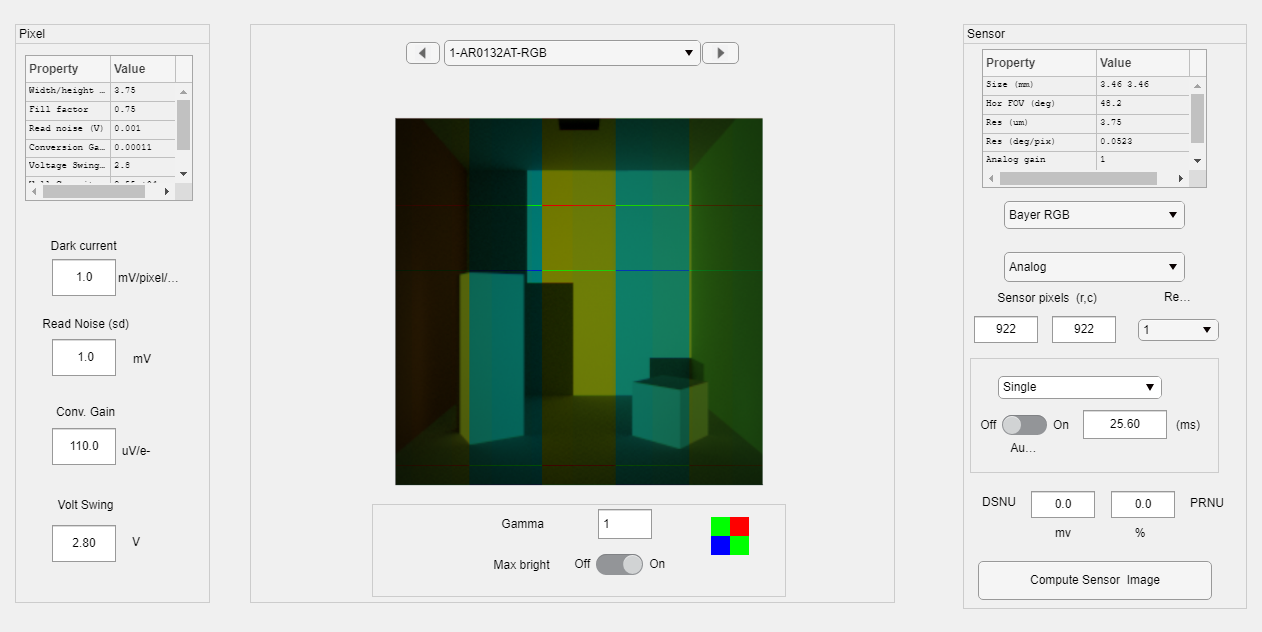

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

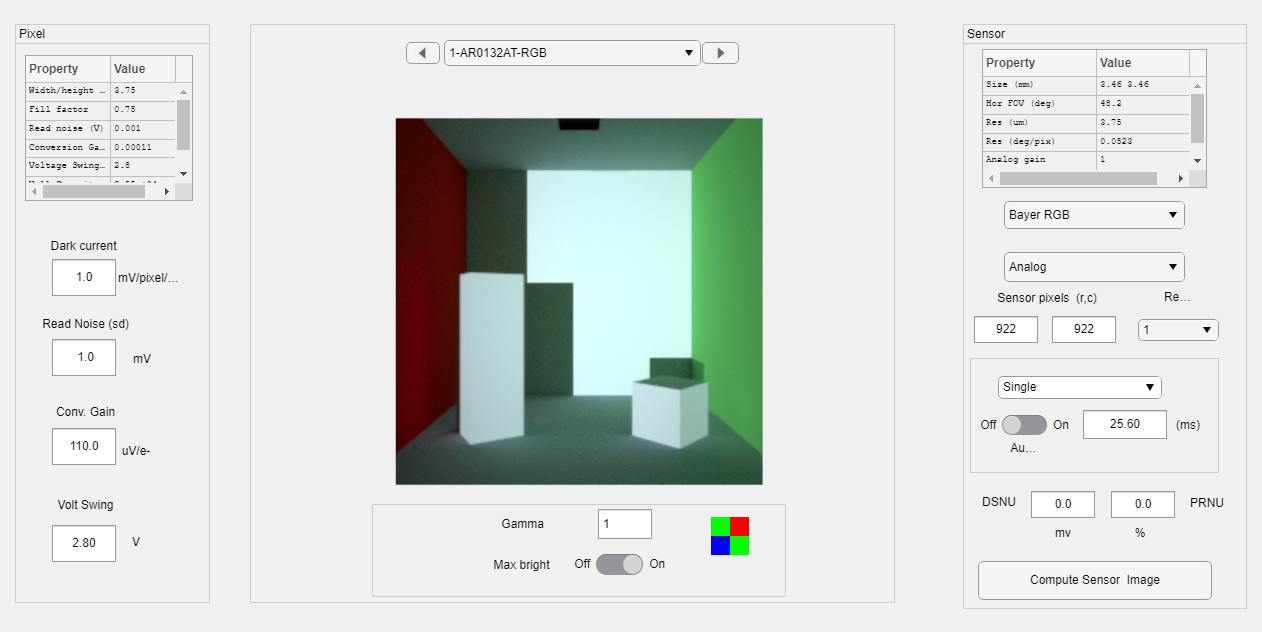

imshow(autoImage);

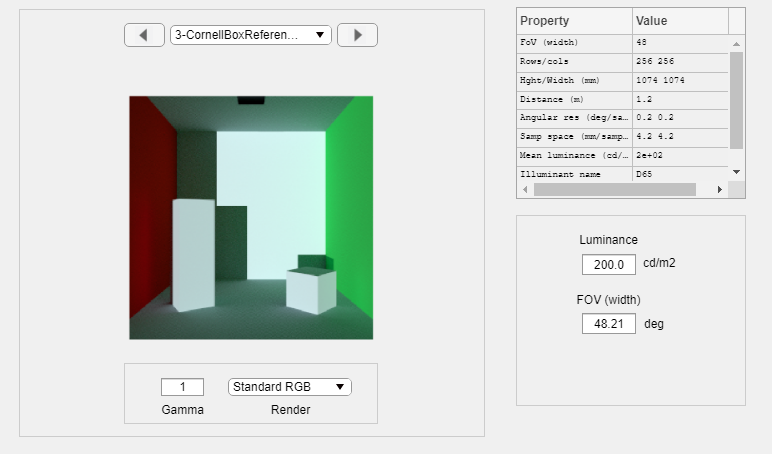

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp9ff6a141_6611_4962_91fb_7f6ae6225687
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp9ff6a141_6611_4962_91fb_7f6ae6225687 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp9ff6a141_6611_4962_91fb_7f6ae6225687\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp9ff6a141_6611_4962_91fb_7f6ae6225687\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp9ff6a141_6611_4962_91fb_7f6ae6225687 -v C:/iset/iset3d/local/CornellBoxReference/tp9ff6a141_6611_4962_91fb_7f6ae6225687:/tp9ff6a141_6611_4962_91fb_7f6ae6225687 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e -v C:/iset/iset3d/local/CornellBoxReference/tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e:/tp1ce45985_6f59_4a31_a8bd_caf6ddb6a52e vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b -v C:/iset/iset3d/local/CornellBoxReference/tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b:/tp98881fbf_49fd_4d90_9a9a_fdfa389bbe0b vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp229da6bc_4fa4_4b61_a54e_628c95075f93
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp229da6bc_4fa4_4b61_a54e_628c95075f93 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp229da6bc_4fa4_4b61_a54e_628c95075f93\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp229da6bc_4fa4_4b61_a54e_628c95075f93\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp229da6bc_4fa4_4b61_a54e_628c95075f93 -v C:/iset/iset3d/local/CornellBoxReference/tp229da6bc_4fa4_4b61_a54e_628c95075f93:/tp229da6bc_4fa4_4b61_a54e_628c95075f93 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"


hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
    'insensorIP', true);

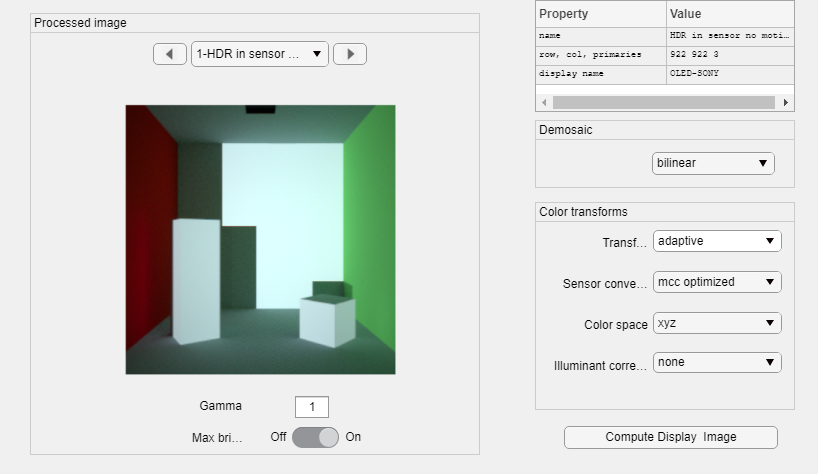

ipWindow(hdrSensorImage);

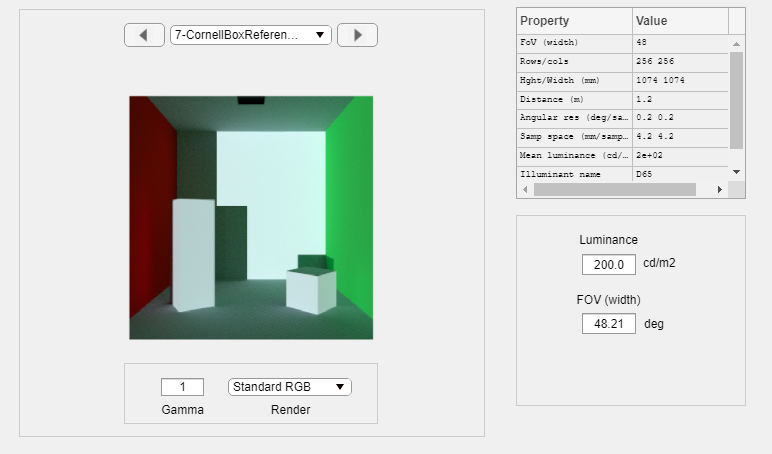

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpaf2ef636_9173_4a8e_9253_03f6023eb622
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpaf2ef636_9173_4a8e_9253_03f6023eb622 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpaf2ef636_9173_4a8e_9253_03f6023eb622\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpaf2ef636_9173_4a8e_9253_03f6023eb622\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpaf2ef636_9173_4a8e_9253_03f6023eb622 -v C:/iset/iset3d/local/CornellBoxReference/tpaf2ef636_9173_4a8e_9253_03f6023eb622:/tpaf2ef636_9173_4a8e_9253_03f6023eb622 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp7e45d7e3_5325_4c16_adca_a1bc0698018c
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp7e45d7e3_5325_4c16_adca_a1bc0698018c 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp7e45d7e3_5325_4c16_adca_a1bc0698018c\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp7e45d7e3_5325_4c16_adca_a1bc0698018c\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp7e45d7e3_5325_4c16_adca_a1bc0698018c -v C:/iset/iset3d/local/CornellBoxReference/tp7e45d7e3_5325_4c16_adca_a1bc0698018c:/tp7e45d7e3_5325_4c16_adca_a1bc0698018c vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpd7bf9c05_4f17_4e3f_94f4_475663f44f60
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpd7bf9c05_4f17_4e3f_94f4_475663f44f60 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpd7bf9c05_4f17_4e3f_94f4_475663f44f60\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpd7bf9c05_4f17_4e3f_94f4_475663f44f60\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpd7bf9c05_4f17_4e3f_94f4_475663f44f60 -v C:/iset/iset3d/local/CornellBoxReference/tpd7bf9c05_4f17_4e3f_94f4_475663f44f60:/tpd7bf9c05_4f17_4e3f_94f4_475663f44f60 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp7cabf987_1d45_41e7_8413_b0ab5b7136af
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp7cabf987_1d45_41e7_8413_b0ab5b7136af 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp7cabf987_1d45_41e7_8413_b0ab5b7136af\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp7cabf987_1d45_41e7_8413_b0ab5b7136af\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp7cabf987_1d45_41e7_8413_b0ab5b7136af -v C:/iset/iset3d/local/CornellBoxReference/tp7cabf987_1d45_41e7_8413_b0ab5b7136af:/tp7cabf987_1d45_41e7_8413_b0ab5b7136af vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

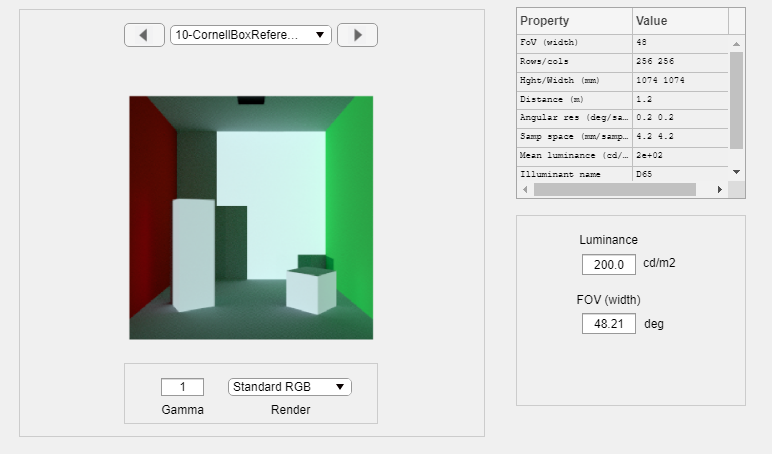

ans = "Scene luminance is: 200.000000"


burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);

ipWindow(burstSensorImage);

pbrtCPScene.cameraMotion = {{'unused', [1, 0, 0], [2, 2, 2]}};
hdrMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', false);
imshow(hdrMotionImage);
imshowpair(hdrImage,hdrMotionImage, 'montage');

burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP with Motion',...
    'insensorIP',false);
imshowpair(hdrMotionImage,burstMotionImage,'montage');
